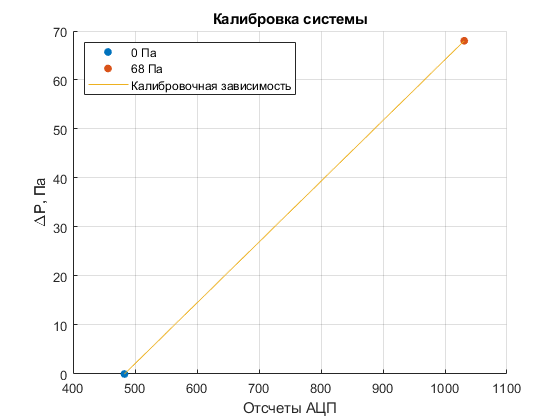

adc1 = fscanf(fopen("calibzeronote.txt"), '%d');
adc2 = fscanf(fopen("calibnote.txt"), '%d');


fclose('all');

pa1 = ones(length(adc1), 1) * 0;
pa2 = ones(length(adc2), 1) * 68;

cAdc = [adc1; adc2];
cPa = [pa1; pa2];

c = polyfit(cAdc, cPa, 1);

cFigure = figure('Name', 'Калибровка', 'NumberTitle', 'off');
hold all;

plot(adc1, pa1, '.', 'MarkerSize', 20);
plot(adc2, pa2, '.', 'MarkerSize', 20);

plot(cAdc, polyval(c, cAdc));

legend('0 Па', '68 Па', 'Калибровочная зависимость', 'Location', 'northwest');

grid on;
xlabel('Отсчеты АЦП');
ylabel("\DeltaP, Па" );
title('Калибровка системы');